Open the Simulink model.

clear;clc;close all;
mdl = "DDPG_qCAS";
open_system(mdl)

Create the observation and action specifications for longitudinal control loop.

obsInfo1 = rlNumericSpec([3 1],...
    'LowerLimit',[-inf -inf 0  ]',...
    'UpperLimit',[ inf  inf inf]');
actInfo1 = rlNumericSpec([1 1]);


Create the observation and action specifications 

obsInfo2 = rlNumericSpec([3 1],...
    'LowerLimit',[-inf -inf 0  ]',...
    'UpperLimit',[ inf  inf inf]');
actInfo2 = rlNumericSpec([1 1]);

Combine the observation and action specifications as a cell array.

obsInfo = {obsInfo1,obsInfo2};
actInfo = {actInfo1,actInfo2};

Create a Simulink environment interface, specifying the block paths for both agent blocks. 

blks = mdl + ["/RL Agent", "/Subsystem/RL Agent1"];
env = rlSimulinkEnv(mdl,blks,obsInfo,actInfo);

Specify a reset function for the environment using the `ResetFcn` property. T

env.ResetFcn = @pfcResetFcn;

## Create Agents

First, fix the random seed for reproducibility.

rng(0)

Both agents operate at the same sample time in this example. Set the sample time value (in seconds).

Ts = 0.1;

agent1 = firstagent(obsInfo1,actInfo1,Ts);
agent2 = secondagent(obsInfo2,actInfo2,Ts);

Tf = 40; % simulation time
maxepisodes = 1420;
maxsteps = ceil(Tf/Ts);
trainingOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes,...
    'MaxStepsPerEpisode',maxsteps,...
    'Verbose',false,...
    'Plots','training-progress',...
    'StopTrainingCriteria','EpisodeCount',...
    'SaveAgentCriteria', "EpisodeReward", 'SaveAgentValue', 3500,...
    'StopTrainingValue',[1420,1420]);
     %'StopTrainingValue',[1420, 1420] ,...
     % 'SaveAgentCriteria', "EpisodeReward", 'SaveAgentValue', 4000);

Train the agents using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training these agents is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

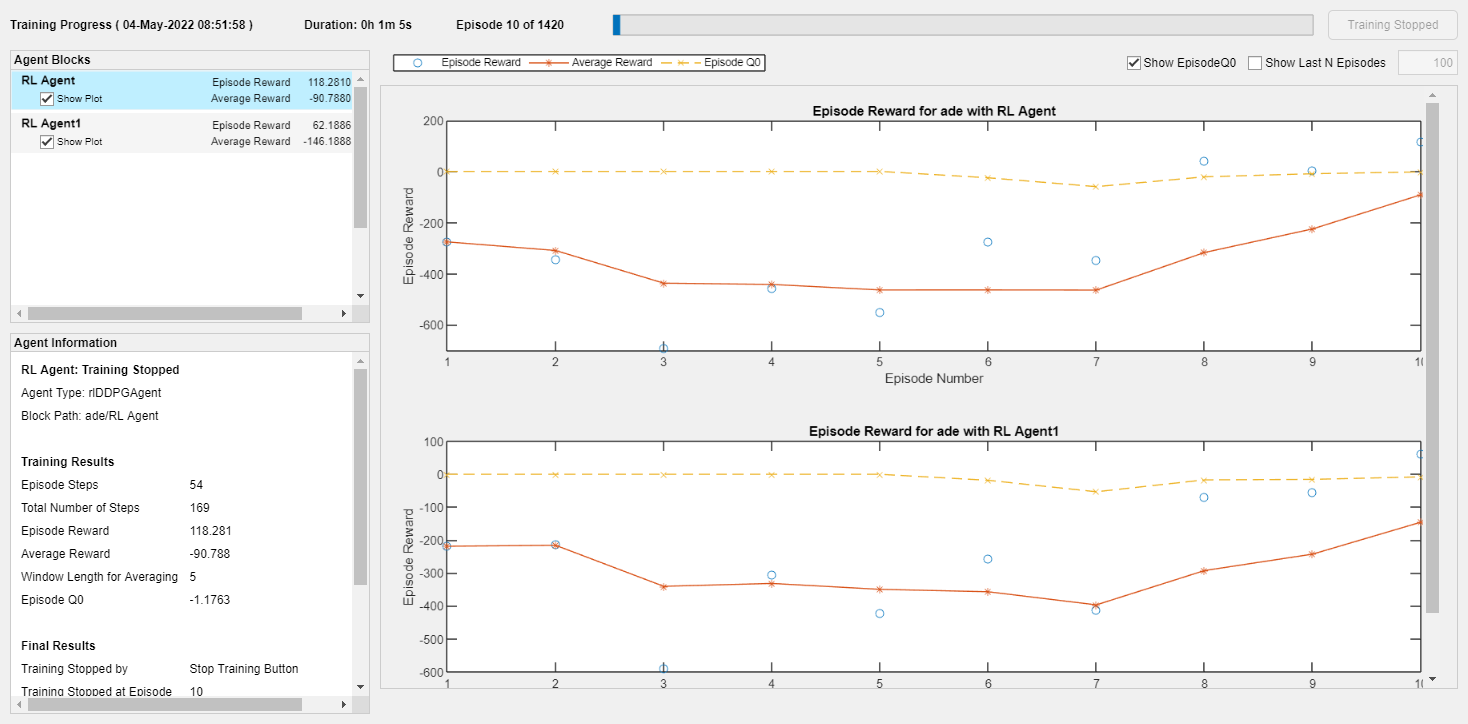

doTraining = false;
if doTraining    
    % Train the agent.
    trainingStats = train([agent1,agent2],env,trainingOpts);
else 
    %Load pretrained agents for the example.
   load('episode1420agent1.mat')
   load('episode1420agent2.mat')
end